clear;
syms t c00 c01 c02 c03 c04 c05;
assume(t,'real');
assume(c00,'real');
assume(c01,'real');
assume(c02,'real');
assume(c03,'real');
assume(c04,'real');
assume(c05,'real');
k=0;
n=0;

m=0;
p00 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=1;
p01 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=2;
p02 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=3;
p03 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=4;
p04 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=5;
p05 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));

F= matriz_F(5,0);

D = blkdiag(F);


C=[c00 ; 
    c01;
    c02;
    c03;
    c04;
    c05];

w=[p00;
    p01;
    p02
    p03;
    p04;
    p05];


y1  = C'*w;
y2 = subs(y1,t,(t^3)/8);

dy1=vpa(C'*D*w,7);

dydy1=vpa(C'*(D^2)*w,5);

eq=vpa(dydy1 + 2*y1 -y1^2 +y2 -sin(t) + sin(t)^2 - sin((t^3)/8)== 0 , 5);
eq1=subs(y1,t,0)== 0;
eq2=vpa(subs(dy1,t,0) - 1 == 0,5);
eq3=vpa(subs(eq,t,0.211),5);
eq4=vpa(subs(eq,t,0.5),5);
eq5=vpa(subs(eq,t,0.67),5);
eq6=vpa(subs(eq,t,0.231),5);

% Suposición inicial
c0 = [0; 0; 0; 0; 0; 0];

% Resolver el sistema de ecuaciones
solucion = fsolve(@sistemaecuacionespunto3, c0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


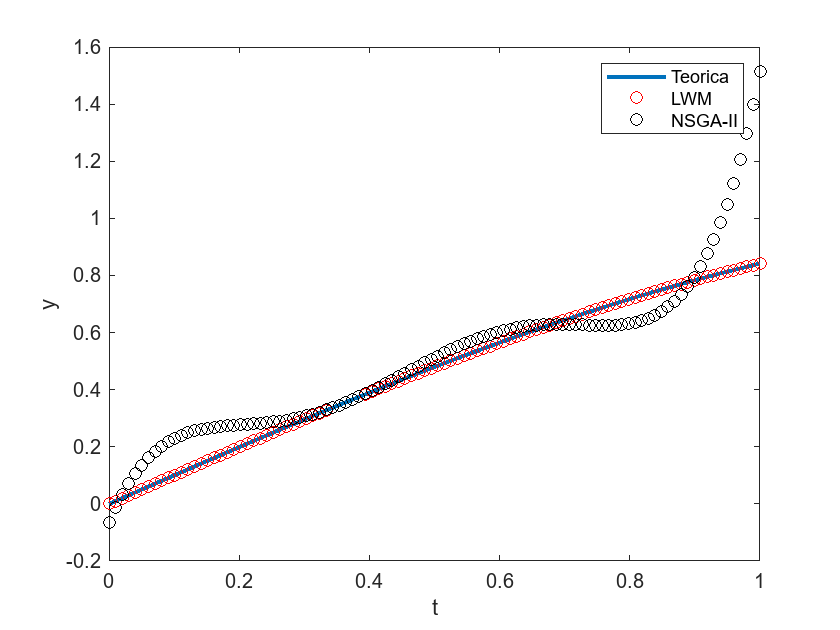


% Mostrar los resultados
c00 = solucion(1);
c01 = solucion(2);
c02 = solucion(3);
c03 = solucion(4);
c04 = solucion(5);
c05 = solucion(6);

sol1 = [c00;
        c01;
        c02;
        c03;
        c04;
        c05];

y = sol1'*w;



sol2 = [0.5049
    0.2532
    0.0382
    0.0581
    0.0443
    0.0594];


y2 = sol2'*w;


t_values = linspace(0, 1, 100);  
y_values = subs(y, {t}, t_values); 
y_gnvals = subs(y2, {t}, t_values);
clf
yt=sin(t_values);
plot(t_values,yt,'LineWidth',2)
hold on
plot(t_values, y_values,'or');
hold on
plot(t_values, y_gnvals,'ok');
xlabel('t');
ylabel('y');
legend("Teorica","LWM","NSGA-II")
hold off


indices = [1,5,10,20, 40, 80,100];

error1 = vpa(abs(y_values(indices) - yt(indices)),4)

$$error1 = \left(\begin{array}{ccccccc} 0 & 2.855e-7 & 5.663e-7 & 8.597e-7 & 1.256e-6 & 2.264e-6 & 2.343e-5 \end{array}\right)$$

error2 = vpa(abs(y_gnvals(indices) - yt(indices)),4)

$$error2 = \left(\begin{array}{ccccccc} 0.06606 & 0.06546 & 0.1264 & 0.08434 & 0.002364 & 0.08488 & 0.671 \end{array}\right)$$

error1-error2

$$ans = \left(\begin{array}{ccccccc} -0.066063131456758128479123115539551 & -0.0654558625446952646598219871521 & -0.12639411183408810757100582122803 & -0.084339753394488070625811815261841 & -0.0023629420313682203413918614387512 & -0.084882689939604460960254073143005 & -0.67100430957179924007505178451538 \end{array}\right)$$

clear;
syms t c00 c01 c02 c03 c04 c05 c06;
assume(t,'real');
assume(c00,'real');
assume(c01,'real');
assume(c02,'real');
assume(c03,'real');
assume(c04,'real');
assume(c05,'real');
assume(c06,'real');
k=0;
n=0;

m=0;
p00 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=1;
p01 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=2;
p02 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=3;
p03 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=4;
p04 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=5;
p05 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));
m=6;
p06 = sqrt(m + 1/2) * (2^((k+1)/2)) * legendreP(m,((2^(k+1))*t - (2*n+1)));

F= matriz_F(6,0);

D = blkdiag(F);


C=[c00 ; 
    c01;
    c02;
    c03;
    c04;
    c05;
    c06];

w=[p00;
    p01;
    p02
    p03;
    p04;
    p05;
    p06];

y1  = C'*w;
y2 = subs(y1,t,(t^3)/8);

dy1=vpa(C'*D*w,7);

dydy1=vpa(C'*(D^2)*w,5);

eq=vpa(dydy1 + 2*y1 -y1^2 +y2 -sin(t) + sin(t)^2 - sin((t^3)/8)== 0 , 5);
eq1=subs(y1,t,0)== 0;
eq2=vpa(subs(dy1,t,0) - 1 == 0,5);
eq3=vpa(subs(eq,t,0.211),5);
eq4=vpa(subs(eq,t,0.5),5);
eq5=vpa(subs(eq,t,0.67),5);
eq6=vpa(subs(eq,t,0.231),5);
eq7=vpa(subs(eq,t,0.0337652),5);

% Suposición inicial
c0 = [0; 0; 0; 0; 0; 0; 0];

% Resolver el sistema de ecuaciones
solucion = fsolve(@sistemaecuacionespunto3, c0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


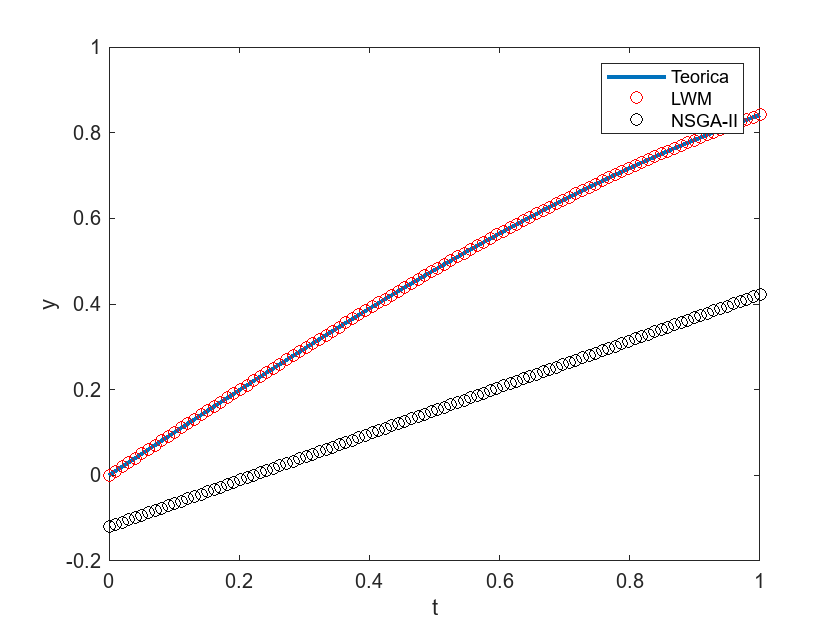


% Mostrar los resultados
c00 = solucion(1);
c01 = solucion(2);
c02 = solucion(3);
c03 = solucion(4);
c04 = solucion(5);
c05 = solucion(6);
c06 = solucion(7);

sol1 = [c00;
        c01;
        c02;
        c03;
        c04;
        c05;
        c06];

y = sol1'*w;



sol2 = [0.151026715566607
    0.156804241106179
    0
    0
    0
    0
    0];


y2 = sol2'*w;


t_values = linspace(0, 1, 100);  
y_values = subs(y, {t}, t_values); 
y_gnvals = subs(y2, {t}, t_values);
clf
yt=sin(t_values);
plot(t_values,yt,'LineWidth',2)
hold on
plot(t_values, y_values,'or');
hold on
plot(t_values, y_gnvals,'ok');
xlabel('t');
ylabel('y');
legend("Teorica","LWM","NSGA-II")
hold off


indices = [1,5,10,20, 40, 80,100];

error1 = vpa(abs(y_values(indices) - yt(indices)),4)

$$error1 = \left(\begin{array}{ccccccc} 9.095e-13 & 2.855e-7 & 5.663e-7 & 8.597e-7 & 1.256e-6 & 2.264e-6 & 2.343e-5 \end{array}\right)$$

error2 = vpa(abs(y_gnvals(indices) - yt(indices)),4)

$$error2 = \left(\begin{array}{ccccccc} 0.1206 & 0.139 & 0.162 & 0.2071 & 0.2904 & 0.4031 & 0.4189 \end{array}\right)$$

error1-error2

$$ans = \left(\begin{array}{ccccccc} -0.12056619687018610420636832714081 & -0.13901205751199086080305278301239 & -0.16196902454430528450757265090942 & -0.20706075320413219742476940155029 & -0.29041168288472363201435655355453 & -0.40305975811497773975133895874023 & -0.41882792624528519809246063232422 \end{array}\right)$$